# Visual Art with MATLAB

This MATLAB Script performs an algorithmic image transformation inspired by a [visual art which demonstrated the transformation using a pasta cutter](https://www.youtube.com/watch?v=f1fXCRtSUWU). 

Import the picture file and visualize it in MATLAB

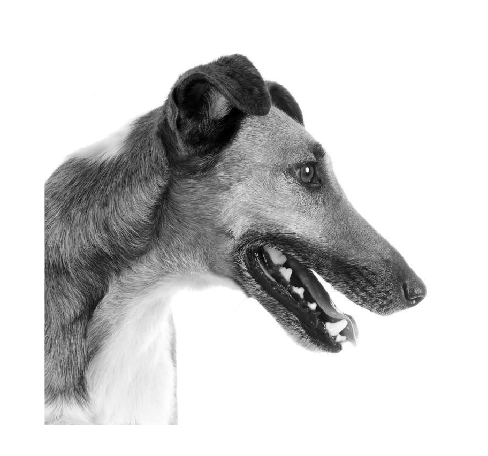

Igr = imread('dogGray.jpg');
imshow(Igr)

Shred and reassemble the original image. Visualize result at the end.

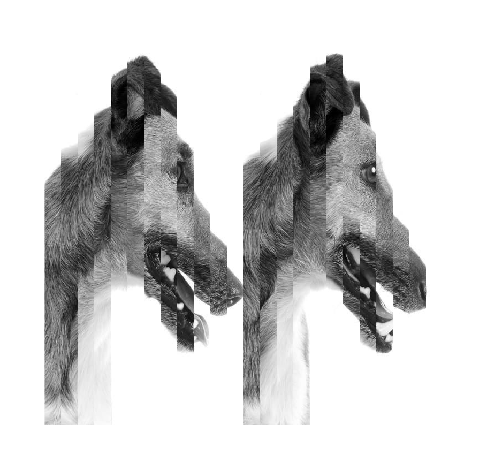

IgFirstShred = shredImage(Igr);
IgFirstAssmbld = assembleImage(IgFirstShred,2);
imshow(IgFirstAssmbld)

Shred and reassemble the image from previous step. Visualize result at the end.

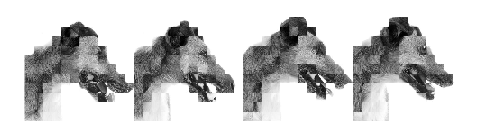

IgSecondShred = shredImage(transpose(IgFirstAssmbld));
IgSecondAssmbld = transpose(assembleImage(IgSecondShred,1));
imshow(IgSecondAssmbld)

Function to shred image into 24 parts

function IgSliced = shredImage(I)
    [Il, Iw] = size(I);
    dl = 24;
    sl = Iw/dl;
    IgSliced = zeros(Il,sl,dl,'uint8');
    sla = 1:sl:Iw;
    for i=1:1:dl
        IgSliced(:,1:sl,i) = I(:, sla(i):sla(i)+sl-1);
    end
end 

Function to assemble shreded images

function IgAssembled = assembleImage(Igsliced, dim)
    [Il, Iw] = size(Igsliced);
    dl = 24;
    IgAssembledOdd = Igsliced(:,:,1:2:dl);
    IgAssembledEven = Igsliced(:,:,2:2:dl);
    IgAssembledOdd2d = reshape(IgAssembledOdd, [Il,Iw/2]);
    IgAssembledEven2d = reshape(IgAssembledEven, [Il,Iw/2]);
    IgAssembled = cat (dim, IgAssembledOdd2d, IgAssembledEven2d);
end 